Ripley dataset

load ripley.mat

Visualize the data. Inspect the data structure: what seems to be important prop-

erties of the data?

2 inputs , binary classification 

 Which classi�cation model do you think you need, based on the

complexity of the data?

linear, RBF 

## Visualize the training data

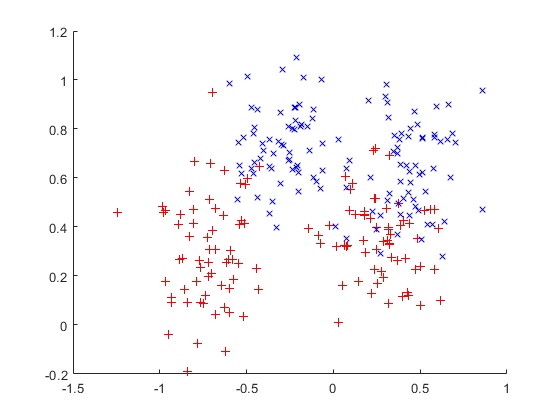

figure 
hold on;
plot(Xtrain(1:125,1), Xtrain(1:125,2), 'r+');
plot(Xtrain(126:250,1), Xtrain(126:250,2), 'bx');

## Visualize the test data

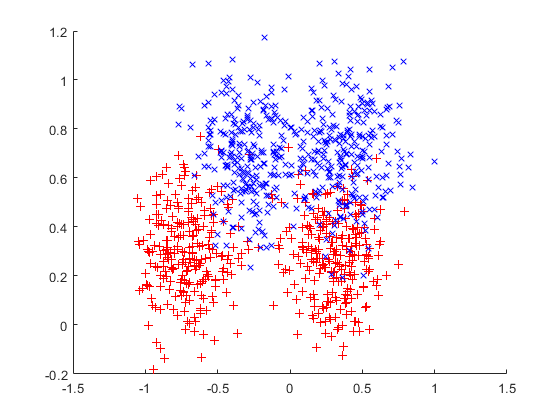

figure 
hold on;
plot(Xtest(1:500,1), Xtest(1:500,2), 'r+');
plot(Xtest(501:1000,1), Xtest(501:1000,2), 'bx');

## Linear model

Try out different models (linear, polynomial, RBF kernel) with tuned hyperparameter

and kernel parameters. Compute the ROC curves. Which model performs best?

Which model would you choose?

Define the model parameters

type = 'c';
kernel_type = 'lin_kernel';

model = {Xtrain,Ytrain,type,[],[],kernel_type};


Tuning the parameter

gam = tunelssvm(model,'simplex','leaveoneoutlssvm', {'misclass'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.0031035
                                          F(X)=         0.14
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  leaveoneoutlssvm
    kernel function                 lin_kernel
 

 3. starting value:                   0.0031035

 Iteration   Func-count    min f(x)    log(gamma)      Procedure

     1           2     1.400000e-01     -5.7752           initial 
     2           4     1.400000e-01     -5.7752           contract inside 
     3           6     1.400000e-01     -5.7752           contract outside 
     4           8     1.400000e-01     -5.7752           contract inside 
optimisation terminated sucessfully (TolFun criterion)

Simplex results: 
X=0.003104  , F(X)

Compute the ROC curves

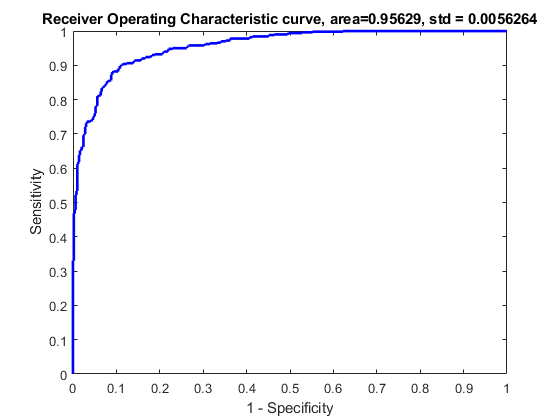

[alpha, b] = trainlssvm({ Xtrain , Ytrain , 'c', gam, [],'lin_kernel'});
[Yest, Ylatent] = simlssvm({ Xtrain , Ytrain , 'c', gam, [],'lin_kernel'},{alpha, b},Xtest);
figure Name 'ROC Linear Kernel'
roc(Ylatent, Ytest);

## Polynomial model

Define the model parameters

type = 'c';
kernel_type = 'poly_kernel';

model = {Xtrain,Ytrain,type,[],[],kernel_type};


Tuning the parameter

[gam,sig2] = tunelssvm(model,'simplex','crossvalidatelssvm', {10, 'misclass'});


   Determine initial hyperparameters for simplex...
  |-                                              -|
  **************************************************

 1. Simulated Annealing results:          [gam]         22.8108
                                          [t]           9.2715
                                          [degree]      5
                                          F(X)=         0.128
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 poly_kernel
 

 3. starting values:                   22.8108      9.27152            5

 Iteration   Func-count    min f(x)    log(gamma)      log(t)        Procedure

     1           3     1.280000e-01     4.3272         2.2269         initial   
     2           5     1.280000e-01     4.3272         2.2269         contract inside   
optimisation terminated sucessfully (TolFun criterion)

Simplex results: 
X=75.734

Compute the ROC curves

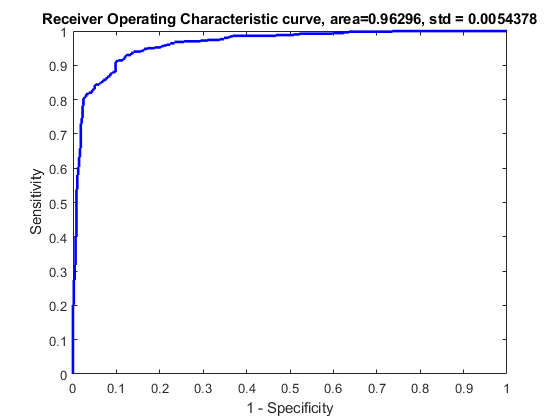

[alpha, b] = trainlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'poly_kernel'});
[Yest, Ylatent] = simlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'poly_kernel'},{alpha, b},Xtest);
figure Name 'ROC Poly Kernel'
roc(Ylatent, Ytest);

## RBF model

Define the model parameters

type = 'c';
kernel_type = 'RBF_kernel';

model = {Xtrain,Ytrain,type,[],[],kernel_type};


Tuning the parameter

[gam,sig2] = tunelssvm(model,'simplex','crossvalidatelssvm', {10, 'misclass'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         5.3899
                                          [sig2]        0.76256
                                          F(X)=         0.116
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   5.3899     0.76256

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     1.160000e-01     2.8845        -0.2711      initial 
     2           7     1.120000e-01     2.2845        -0.2711      shrink 
     3           9     1.120000e-01     2.2845        -0.2711      contract inside 
     4          11     1.120000e-01     2.2845        -0.2711    

Compute the ROC curves

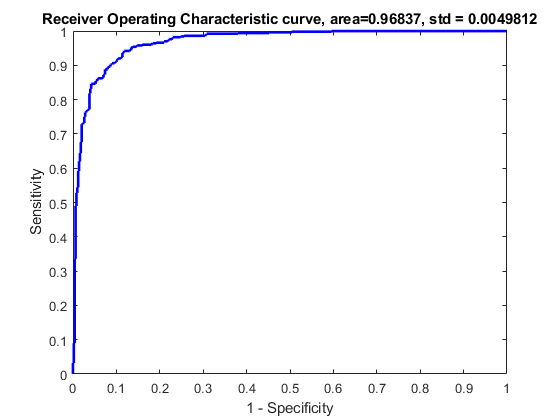

[alpha, b] = trainlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'RBF_kernel'});
[Yest, Ylatent] = simlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'RBF_kernel'},{alpha, b},Xtest);
figure Name 'ROC Poly Kernel'
roc(Ylatent, Ytest);